# **HW Set 8 - RBE 502**

clc; clear all;
syms m1 m2 l1 l2 q1 q2 q1dot q2dot g e1 e2 e3 e4 qd1 qd2

x = [q1; q2; q1dot; q2dot;]

$$x = \left(\begin{array}{c} q_{1}\\ q_{2}\\ \mathrm{q1dot}\\ \mathrm{q2dot} \end{array}\right)$$

xd = [qd1; qd2; 0; 0;]

$$xd = \left(\begin{array}{c} {\mathrm{qd}}_{1}\\ {\mathrm{qd}}_{2}\\ 0\\ 0 \end{array}\right)$$

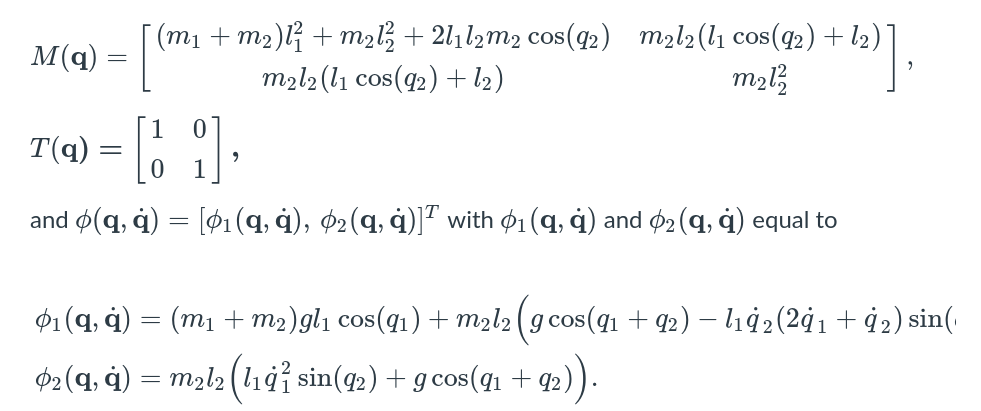

% M = [
%         (m1+m2)*l1^2 + m2*l2^2 + 2*l1*l2*m2*cos(q2)     m2*l2*(l1*cos(q2) + l2);
%         m2*l2*(l1*cos(q2)+l2)                           m2*l2^2
% 
%     ]
T = [1  0;  0   1]

T =      1     0
     0     1


 
phi1 = (m1+m2)*g*l1*cos(q1) + m2*l2*(g*cos(q1+q2)-l1*q2dot*(2*q1dot+q2dot)*sin(q2))

$$phi1 = l_{2}\,m_{2}\,\left(g\,\cos\left(q_{1}+q_{2}\right)-l_{1}\,\mathrm{q2dot}\,\sin\left(q_{2}\right)\,\left(2\,\mathrm{q1dot}+\mathrm{q2dot}\right)\right)+g\,l_{1}\,\cos\left(q_{1}\right)\,\left(m_{1}+m_{2}\right)$$

phi2 = m2*l2*(l1*q1dot^2*sin(q2)+g*cos(q1+q2))

$$phi2 = l_{2}\,m_{2}\,\left(l_{1}\,\sin\left(q_{2}\right)\,{\mathrm{q1dot}}^{2}+g\,\cos\left(q_{1}+q_{2}\right)\right)$$

% Factor out for C
phi1_factored = [ 0;    0;      -2*l1*sin(q2);     -l1*q2dot*sin(q2);]

$$phi1\_factored = \left(\begin{array}{c} 0\\ 0\\ -2\,l_{1}\,\sin\left(q_{2}\right)\\ -l_{1}\,\mathrm{q2dot}\,\sin\left(q_{2}\right) \end{array}\right)$$

phi1_factored = [ -2*l1*sin(q2);     -l1*q2dot*sin(q2);]

$$phi1\_factored = \left(\begin{array}{c} -2\,l_{1}\,\sin\left(q_{2}\right)\\ -l_{1}\,\mathrm{q2dot}\,\sin\left(q_{2}\right) \end{array}\right)$$


phi2_factored = [ 0;    0;      m2*l2*l1*q1dot*sin(q2);     0;]

$$phi2\_factored = \left(\begin{array}{c} 0\\ 0\\ l_{1}\,l_{2}\,m_{2}\,\mathrm{q1dot}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$

phi2_factored = [ m2*l2*l1*q1dot*sin(q2);     0;]

$$phi2\_factored = \left(\begin{array}{c} l_{1}\,l_{2}\,m_{2}\,\mathrm{q1dot}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$


C = phi1_factored + phi2_factored

$$C = \left(\begin{array}{c} l_{1}\,l_{2}\,m_{2}\,\mathrm{q1dot}\,\sin\left(q_{2}\right)-2\,l_{1}\,\sin\left(q_{2}\right)\\ -l_{1}\,\mathrm{q2dot}\,\sin\left(q_{2}\right) \end{array}\right)$$

C = simplify(C)

$$C = \left(\begin{array}{c} l_{1}\,\sin\left(q_{2}\right)\,\left(l_{2}\,m_{2}\,\mathrm{q1dot}-2\right)\\ -l_{1}\,\mathrm{q2dot}\,\sin\left(q_{2}\right) \end{array}\right)$$


%Because of vector form:
C = [-2*l1*sin(q2)+l1*l2*m2*q1dot*sin(q2) 0;
     0  -l1*q2dot*sin(q2);]

$$C = \left(\begin{array}{cc} l_{1}\,l_{2}\,m_{2}\,\mathrm{q1dot}\,\sin\left(q_{2}\right)-2\,l_{1}\,\sin\left(q_{2}\right) & 0\\ 0 & -l_{1}\,\mathrm{q2dot}\,\sin\left(q_{2}\right) \end{array}\right)$$



% Define potential energy of the system
pe_1 = (m1+m2)*g*l1*sin(q1)

$$pe\_1 = g\,l_{1}\,\sin\left(q_{1}\right)\,\left(m_{1}+m_{2}\right)$$

pe_2 = m2 * g * (l1*sin(q1)+l2 * sin(q1+q2))

$$pe\_2 = g\,m_{2}\,\left(l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)$$

p_energy = pe_1 + pe_2

$$p\_energy = g\,m_{2}\,\left(l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)+g\,l_{1}\,\sin\left(q_{1}\right)\,\left(m_{1}+m_{2}\right)$$


q = [q1; q2;]

$$q = \left(\begin{array}{c} q_{1}\\ q_{2} \end{array}\right)$$


G_func = gradient(p_energy, q)

$$G\_func = \left(\begin{array}{c} g\,m_{2}\,\left(l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)+g\,l_{1}\,\cos\left(q_{1}\right)\,\left(m_{1}+m_{2}\right)\\ g\,l_{2}\,m_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$


syms m1 m2 l1 l2 q1 q2 q1dot q2dot g e1 e2 e3 e4 qd1 qd2
symspecs = struct("m1", m1, "m2", m2, "g", g, "l1", l1, "l2", l2);


global xd1 xd2 xd3;
xd1 = [0; pi/2; 0; 0;]

xd1 =          0
    1.5708
         0
         0


xd2 = [pi/2; 0; 0; 0;]

xd2 =     1.5708
         0
         0
         0


xd3 = [pi/4; pi/4; 0; 0;]

xd3 =     0.7854
    0.7854
         0
         0



realspecs = struct("m1", 10, "m2", 4, "l1", 1, "l2", 2, "g", 9.81)

realspecs = struct with fields:
    m1: 10
    m2: 4
    l1: 1
    l2: 2
     g: 9.8100




f = @(x, specs) [
    % Qdot in the state is a 2x1 of q1dot and q2dot, which are in
    % the bottom half of the state.
    x(3);
    x(4);
    % Then we place in our M-1*phi(q, qdot) which results in two equations
    -M(x,specs)^-1*phi(x, specs)
]

f = function_handle with value:
    @(x,specs)[x(3);x(4);-M(x,specs)^-1*phi(x,specs)]



g = @(x, specs) [
    zeros(2,2);
    M(x, specs)^-1*T
]

g = function_handle with value:
    @(x,specs)[zeros(2,2);M(x,specs)^-1*T]



% xd1

fe = @(e, specs) -f(xd1-e, specs)

fe = function_handle with value:
    @(e,specs)-f(xd1-e,specs)


ge = @(e, specs) -g(xd1-e, specs)

ge = function_handle with value:
    @(e,specs)-g(xd1-e,specs)



Kp = [2 0; 0 12;]

Kp =      2     0
     0    12


Kd = [3 0; 0 7;]

Kd =      3     0
     0     7


K = [Kp Kd]

K =      2     0     3     0
     0    12     0     7


u = @(qd, q, specs) K*(qd-q) + G(q, specs)

u = function_handle with value:
    @(qd,q,specs)K*(qd-q)+G(q,specs)



de = @(qd, e, u, specs) fe(e, specs) + ge(e, specs)*u(qd, qd-e, specs)

de = function_handle with value:
    @(qd,e,u,specs)fe(e,specs)+ge(e,specs)*u(qd,qd-e,specs)




x0 = [0; 0; 0; 0;]

x0 =      0
     0
     0
     0


tspan = 0:0.1:90;

e0 = xd1 - x0

e0 =          0
    1.5708
         0
         0


[t,e]=ode45(@(t,e) de(xd1, e, u, realspecs), tspan, e0)

t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


e =          0    1.5708         0         0
    0.0131    1.5457    0.2508   -0.4823
    0.0481    1.4781    0.4403   -0.8501
    0.0992    1.3793    0.5716   -1.1087
    0.1606    1.2598    0.6494   -1.2663
    0.2275    1.1290    0.6816   -1.3376
    0.2958    0.9945    0.6791   -1.3435
    0.3626    0.8617    0.6527   -1.3048
    0.4258    0.7346    0.6118   -1.2394
    0.4845    0.6146    0.5627   -1.1595


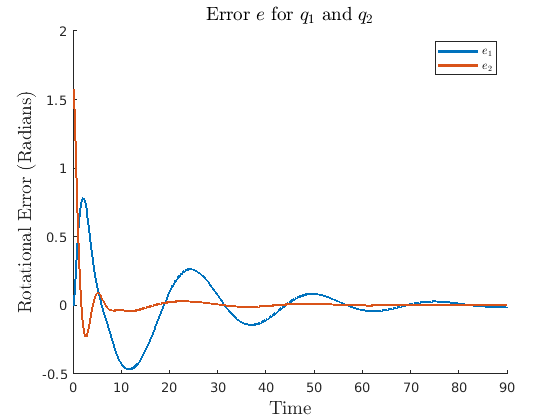


figure
title("Error $e$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Error (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, e(:,1), 'LineWidth', 2)
plot(t, e(:,2), 'LineWidth', 2)

legend(["$e_1$", "$e_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/error-b1.png','Resolution',300)

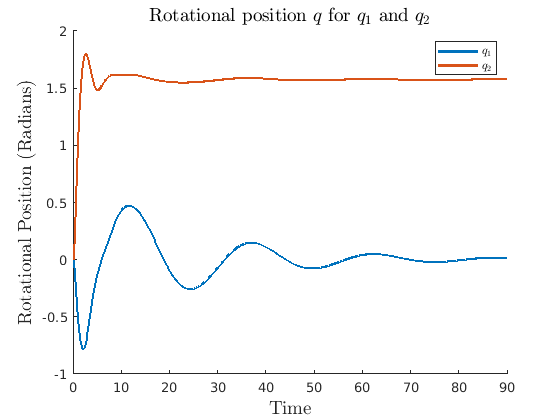


figure
title("Rotational position $q$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Position (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, xd1(1) - e(:,1), 'LineWidth', 2)
plot(t, xd1(2) - e(:,2), 'LineWidth', 2)

legend(["$q_1$", "$q_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/rotational-position-b1.png','Resolution',300)

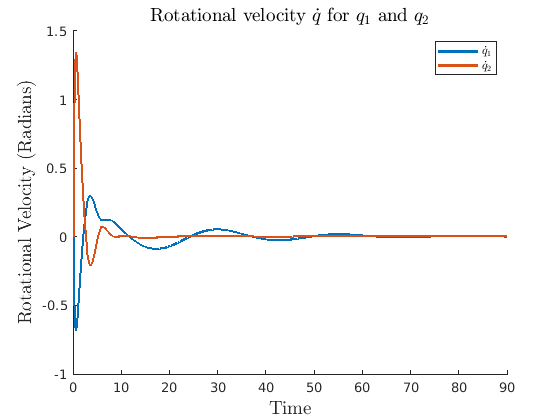


figure
title("Rotational velocity $\dot{q}$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Velocity (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, xd1(3) - e(:,3), 'LineWidth', 2)
plot(t, xd1(4) - e(:,4), 'LineWidth', 2)

legend(["$\dot{q}_1$", "$\dot{q}_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/rotational-velocity-b1.png','Resolution',300)



% xd2


fe = @(e, specs) -f(xd2-e, specs)

fe = function_handle with value:
    @(e,specs)-f(xd2-e,specs)


ge = @(e, specs) -g(xd2-e, specs)

ge = function_handle with value:
    @(e,specs)-g(xd2-e,specs)


u = @(qd, q, specs) K*(qd-q) + G(q, specs)

u = function_handle with value:
    @(qd,q,specs)K*(qd-q)+G(q,specs)


de = @(qd, e, u, specs) fe(e, specs) + ge(e, specs)*u(qd, qd-e, specs)

de = function_handle with value:
    @(qd,e,u,specs)fe(e,specs)+ge(e,specs)*u(qd,qd-e,specs)



x0 = [0; 0; 0; 0;]

x0 =      0
     0
     0
     0


tspan = 0:0.1:90;

e0 = xd2 - x0

e0 =     1.5708
         0
         0
         0



fe = @(e, specs) -f(xd2-e, specs)

fe = function_handle with value:
    @(e,specs)-f(xd2-e,specs)


ge = @(e, specs) -g(xd2-e, specs)

ge = function_handle with value:
    @(e,specs)-g(xd2-e,specs)


tspan = 0:0.1:90;

[t,e]=ode45(@(t,e) de(xd2, e, u, realspecs), tspan, e0)

t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


e =     1.5708         0         0         0
    1.5693    0.0022   -0.0285    0.0418
    1.5653    0.0080   -0.0517    0.0736
    1.5592    0.0166   -0.0699    0.0963
    1.5514    0.0270   -0.0838    0.1110
    1.5425    0.0386   -0.0941    0.1188
    1.5327    0.0506   -0.1012    0.1209
    1.5223    0.0626   -0.1059    0.1183
    1.5116    0.0741   -0.1085    0.1121
    1.5007    0.0849   -0.1097    0.1032


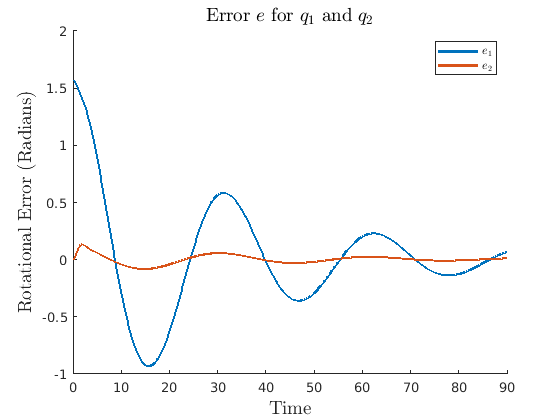


figure
title("Error $e$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Error (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, e(:,1), 'LineWidth', 2)
plot(t, e(:,2), 'LineWidth', 2)

legend(["$e_1$", "$e_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/error-b2.png','Resolution',300)

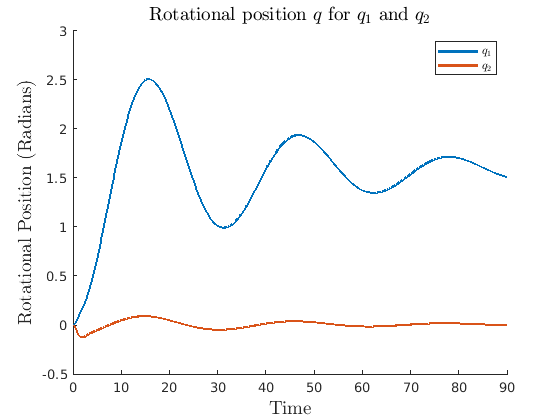


figure
title("Rotational position $q$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Position (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, xd2(1) - e(:,1), 'LineWidth', 2)
plot(t, xd2(2) - e(:,2), 'LineWidth', 2)

legend(["$q_1$", "$q_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/rotational-position-b2.png','Resolution',300)

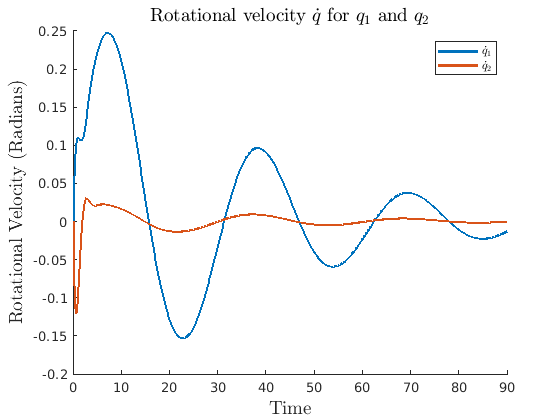


figure
title("Rotational velocity $\dot{q}$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Velocity (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, xd2(3) - e(:,3), 'LineWidth', 2)
plot(t, xd2(4) - e(:,4), 'LineWidth', 2)

legend(["$\dot{q}_1$", "$\dot{q}_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/rotational-velocity-b2.png','Resolution',300)



% xd3



fe = @(e, specs) -f(xd3-e, specs)

fe = function_handle with value:
    @(e,specs)-f(xd3-e,specs)


ge = @(e, specs) -g(xd3-e, specs)

ge = function_handle with value:
    @(e,specs)-g(xd3-e,specs)



Kp = [2 0; 0 12;]

Kp =      2     0
     0    12


Kd = [3 0; 0 7;]

Kd =      3     0
     0     7


K = [Kp Kd]

K =      2     0     3     0
     0    12     0     7


u = @(qd, q, specs) K*(qd-q) + G(q, specs)

u = function_handle with value:
    @(qd,q,specs)K*(qd-q)+G(q,specs)



de = @(qd, e, u, specs) fe(e, specs) + ge(e, specs)*u(qd, qd-e, specs)

de = function_handle with value:
    @(qd,e,u,specs)fe(e,specs)+ge(e,specs)*u(qd,qd-e,specs)




x0 = [0; 0; 0; 0;]

x0 =      0
     0
     0
     0


tspan = 0:0.1:90;

e0 = xd3 - x0

e0 =     0.7854
    0.7854
         0
         0



[t,e]=ode45(@(t,e) de(xd3, e, u, realspecs), tspan, e0)

t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


e =     0.7854    0.7854         0         0
    0.7912    0.7739    0.1111   -0.2203
    0.8067    0.7430    0.1947   -0.3891
    0.8293    0.6977    0.2533   -0.5109
    0.8566    0.6423    0.2893   -0.5906
    0.8865    0.5808    0.3061   -0.6338
    0.9173    0.5165    0.3069   -0.6469
    0.9475    0.4522    0.2951   -0.6363
    0.9760    0.3899    0.2741   -0.6083
    1.0021    0.3309    0.2466   -0.5682


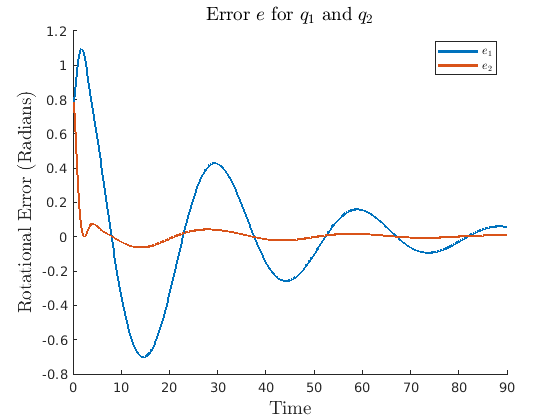


figure
title("Error $e$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Error (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, e(:,1), 'LineWidth', 2)
plot(t, e(:,2), 'LineWidth', 2)

legend(["$e_1$", "$e_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/error-b3.png','Resolution',300)

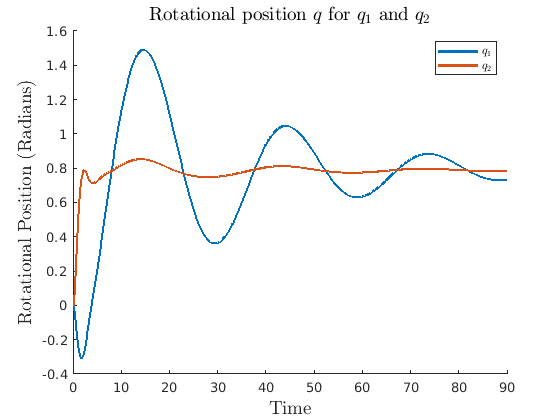


figure
title("Rotational position $q$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Position (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, xd3(1) - e(:,1), 'LineWidth', 2)
plot(t, xd3(2) - e(:,2), 'LineWidth', 2)

legend(["$q_1$", "$q_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/rotational-position-b3.png','Resolution',300)

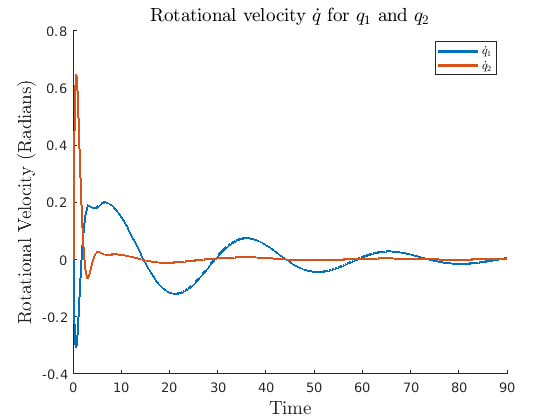


figure
title("Rotational velocity $\dot{q}$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Velocity (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, xd3(3) - e(:,3), 'LineWidth', 2)
plot(t, xd3(4) - e(:,4), 'LineWidth', 2)

legend(["$\dot{q}_1$", "$\dot{q}_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/rotational-velocity-b3.png','Resolution',300)

function output = M(x, specs)
    m1 = specs.m1;
    m2 = specs.m2;
    l1 = specs.l1;
    l2 = specs.l2;
    g = specs.g;

    q1 = x(1);
    q2 = x(2);
    q1dot = x(3);
    q2dot = x(4);
    output = [
        (m1+m2)*l1^2 + m2*l2^2 + 2*l1*l2*m2*cos(q2)     m2*l2*(l1*cos(q2) + l2);
        m2*l2*(l1*cos(q2)+l2)                           m2*l2^2
    ];
end
function output = phi(x, specs)
    m1 = specs.m1;
    m2 = specs.m2;
    l1 = specs.l1;
    l2 = specs.l2;
    g = specs.g;
    
    q1 = x(1);
    q2 = x(2);
    q1dot = x(3);
    q2dot = x(4);
    output = [
        (m1+m2)*g*l1*cos(q1) + m2*l2*(g*cos(q1+q2)-l1*q2dot*(2*q1dot+q2dot)*sin(q2))
        m2*l2*(l1*q1dot^2*sin(q2)+g*cos(q1+q2))
    ];
end
function output = G(q, specs)
    m1 = specs.m1;
    m2 = specs.m2;
    l1 = specs.l1;
    l2 = specs.l2;
    g = specs.g;
    
    output = [
        g*m2*( l2*cos(q(1)+q(2))+l1*cos(q(1)) ) + g*l1*m1*cos(q(1));
        g*l2*m2*cos(q(1)+q(2));
    ];
end